# Diseño de alcantarillado

**Título completo:** Diseño de redes de alcantarillado sanitario

## Contexto

El **diseño de alcantarillado** es fundamental para el desarrollo urbano sostenible, ya que asegura la recolección y disposición adecuada de las aguas residuales y pluviales. Su **importancia** radica en varios aspectos clave:

- **Salud pública**: Un sistema de alcantarillado eficiente previene la propagación de enfermedades transmitidas por el agua al eliminar de manera segura las aguas residuales, evitando que entren en contacto con las personas y el suministro de agua potable.

- **Prevención de inundaciones**: El diseño adecuado de alcantarillado pluvial ayuda a gestionar el agua de lluvia, reduciendo el riesgo de inundaciones urbanas y los daños a infraestructura, viviendas y negocios.

- **Protección ambiental**: Un sistema bien diseñado minimiza la descarga de contaminantes en ríos, lagos y mares, ayudando a preservar los ecosistemas acuáticos y la calidad del agua.

- **Sostenibilidad urbana**: Facilita el crecimiento ordenado de las ciudades, garantizando que las nuevas áreas urbanas cuenten con infraestructura sanitaria que permita una vida saludable y segura.

Por lo tanto, el diseño de alcantarillado es crucial no solo para la calidad de vida de la población, sino también para la protección del medio ambiente y la resiliencia frente a fenómenos naturales como lluvias intensas.

**Fig. 1.** Ilustriación de un sistema de alcantarillado.

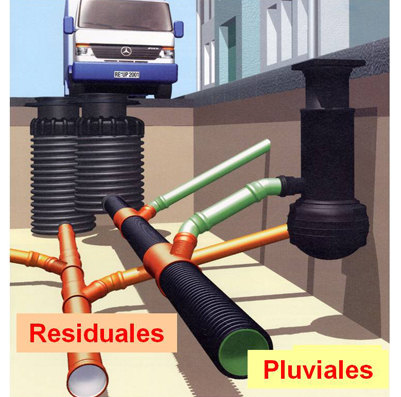

*Tomado de *[*smasa*](https://www.smasa.net/redes-de-saneamiento-no-separativas/).

## Requisitos

Los principales requisitos son el conocimiento y dominio sobre:

- **Hidráulica.** Especialmente lo que se refiere al flujo en tuberías.

- **Geometría.** Esencial para entender y utilizar las expresiones matemáticas del diseño.

- **Diseño de alcantarillado.** Indispensable para utilizar las fórmulas, realizar el diseño y analizar los resultados obtenidos.

## Entradas

Las entradas se resumen a una sola: un archivo Excel con 3 hojas. Cada hoja corresponde a la siguiente información:

- `INFORMACIÓN_POZOS`: Información sobre los pozos.

- `INFORMACIÓN_TUBERÍAS`: Información sobre las tuberías.

- `DIÁMETROS_TUBERÍAS`: Información sobre los diámetros comerciales disponibles para las tuberías.

***No se debe modificar el formato del archivo Excel ni los nombres de las hojas. Únicamente se debe añadir o quitar información en cada hoja según proyecto en cuestión.***

nombre_archivo = "aux_entradas.xlsx";

## Procedimiento

El procedimiento a seguir para el diseño de la red de alcantarillado es el siguiente:

- Importación de información inicial (entradas)

- Calcular la pendiente de cada tubería

- Calcular el caudal de diseño de cada tubería

- Diseñar tuberías

### 1. Importación de información inicial (entradas)

% Importación de la información de los pozos.
pozos_tbl = readtable(nombre_archivo, "Sheet", "INFORMACIÓN_POZOS", "VariableNamingRule", "preserve");
pozos_tbl.Properties.VariableNames = ["No." "Cota" "Cabecera"];
pozos_tbl.Properties.VariableUnits = ["" "m.s.n.m." ""];
head(pozos_tbl)

    No.    Cota     Cabecera
    ___    _____    ________

     1      1000     true   
     2      1001     true   
     3       998     false  
     4       997     false  
     5     997.5     true   
     6       996     false  
     7       994     false  



% Importación de la información de las tuberías.
tuberias_tbl = readtable(nombre_archivo, "Sheet", "INFORMACIÓN_TUBERÍAS", "VariableNamingRule", "preserve");
tuberias_tbl.Properties.VariableNames = ["No." "Pozo inicial" "Pozo final" "Caudal individual" "Longitud horizontal" "Rugosidad absoluta"];
tuberias_tbl.Properties.VariableUnits = ["" "" "" "L/s" "m" "mm"];
head(tuberias_tbl)

    No.    Pozo inicial    Pozo final    Caudal individual    Longitud horizontal    Rugosidad absoluta
    ___    ____________    __________    _________________    ___________________    __________________

     1          1              3                 50                   70                   0.0015      
     2          2              3                100                   80                   0.0015      
     3          3              4                150                   50                   0.0015      
     4          4              6                100                   60                   0.0015      
     5          5              6                150                   50                   0.0015      
     6          6              7                 50                

% Importación de la información de los diámetros comerciales de tuberías.
diametros_tbl = readtable(nombre_archivo, "Sheet", "DIÁMETROS_TUBERÍAS", "VariableNamingRule", "preserve");
diametros_tbl.Properties.VariableNames = ["No." "Diámetro interno"];
diametros_tbl.Properties.VariableUnits = ["" "mm"];
head(diametros_tbl)

    No.    Diámetro interno
    ___    ________________

     1           110       
     2           160       
     3           200       
     4           250       
     5           300       
     6           600       
     7           400       
     8           500       



### 2. Calcular la pendiente de cada tubería

% Calcular la longitud vertical de las tuberías.
cota_superior = pozos_tbl{tuberias_tbl.("Pozo inicial"), "Cota"};   % [m]
cota_inferior = pozos_tbl{tuberias_tbl.("Pozo final"), "Cota"};     % [m]
longitud_vertical = cota_superior - cota_inferior;                  % [m]

% Extraer la longitud horizontal de las tuberías.
longitud_horizontal = tuberias_tbl.("Longitud horizontal");         % [m]

% Calcular la pendiente de las tuberías.
S = longitud_vertical ./ longitud_horizontal;                       % [m/m]

% Verificar que las pendientes sean positivas: sentido de flujo correcto.
if any(S <= 0)
    msg = "Mal establecido el sentido de flujo de las siguientes tuberías: " + ...
        replace(mat2str(tuberias_tbl{S <= 0, "No."}), ";", " ") + ...
        ". Sus pendientes son " + mat2str(S(S <= 0)) + ", respectivamente.";
    error(msg)
end

% Añadir pendientes a la tabla de tuberías.
tuberias_tbl = [tuberias_tbl table(S)];
tuberias_tbl.Properties.VariableNames(end) = "Pendiente";
tuberias_tbl.Properties.VariableUnits(end) = "m/m";
head(tuberias_tbl)

    No.    Pozo inicial    Pozo final    Caudal individual    Longitud horizontal    Rugosidad absoluta    Pendiente
    ___    ____________    __________    _________________    ___________________    __________________    _________

     1          1              3                 50                   70                   0.0015          0.028571 
     2          2              3                100                   80                   0.0015            0.0375 
     3          3              4                150                   50                   0.0015              0.02 
     4          4              6                100                   60                   0.0015          0.016667 
     5          5              6                150        

### 3. Calcular el caudal de diseño de cada tubería

% Identificar pozos y tuberías de cabecera.
pozos_cabecera_idx = pozos_tbl{pozos_tbl.Cabecera, "No."};
tuberias_cabecera_idx = tuberias_tbl{pozos_cabecera_idx, "No."};

% Añadir caudal de diseño a la tabla de tuberías.
tuberias_tbl = [tuberias_tbl table(zeros(height(tuberias_tbl), 1))];
tuberias_tbl.Properties.VariableNames(end) = "Caudal diseño";
tuberias_tbl.Properties.VariableUnits(end) = "L/s";
tuberias_tbl = movevars(tuberias_tbl, "Caudal diseño", "After", "Caudal individual");
tuberias_tbl.("Caudal diseño")(tuberias_cabecera_idx) = tuberias_tbl.("Caudal individual")(tuberias_cabecera_idx);

while any(tuberias_tbl.("Caudal diseño") == 0)

    % Indexar tuberías con caudales de diseño distintos de cero.
    tuberias_con_caudal = tuberias_tbl.("No.")(tuberias_tbl.("Caudal diseño") ~= 0);
    
    % Obtener tuberías que inician a partir del fin de las tuberías anteriores.
    tuberias_sin_caudal = tuberias_tbl.("No.")(unique(tuberias_tbl.("Pozo final")(tuberias_con_caudal)));
    
    % Para cada tubería sin caudal, verificar que las tuberías anteriores sí tengan caudal.
    for tuberia_actual = tuberias_sin_caudal'
    
        tuberias_anteriores = tuberias_tbl.("No.")(tuberias_tbl.("Pozo final") == tuberias_tbl.("Pozo inicial")(tuberia_actual));
        caudales_anteriores = tuberias_tbl.("Caudal diseño")(tuberias_anteriores);
        caudales_anteriores_completos = ~any(caudales_anteriores == 0);
    
        if caudales_anteriores_completos
            tuberias_tbl.("Caudal diseño")(tuberia_actual) = tuberias_tbl.("Caudal individual")(tuberia_actual) + ...
                sum(caudales_anteriores);
        end
    
    end

end

head(tuberias_tbl)

    No.    Pozo inicial    Pozo final    Caudal individual    Caudal diseño    Longitud horizontal    Rugosidad absoluta    Pendiente
    ___    ____________    __________    _________________    _____________    ___________________    __________________    _________

     1          1              3                 50                 50                 70                   0.0015          0.028571 
     2          2              3                100                100                 80                   0.0015            0.0375 
     3          3              4                150                300                 50                   0.0015              0.02 
     4          4              6                100      

### 4. Diseñar tuberías

% Prelocalizar celda para el diseño de las tuberías.
cantidad_tuberias = height(tuberias_tbl);
diseno_tuberias_cell = cell(cantidad_tuberias, 1);

% Diseñar cada tubería de cabecera.
for i = 1:cantidad_tuberias

    % Extraer información de la tubería actual.
    S = tuberias_tbl{i, "Pendiente"};                                       % [m/m]
    Q = tuberias_tbl{i, "Caudal diseño"};                                   % [L/s]
    Q = Q / 1000;                                                           % [m3/s]
    k = tuberias_tbl{i, "Rugosidad absoluta"};                              % [mm]
    k = k / 1000;                                                           % [m]
    
    % Diseñar buscando el diámetro óptimo: el más pequeño.
    j = 1;
    while true
        D = diametros_tbl{j, "Diámetro interno"};                           % [mm]
        D = D / 1000;                                                       % [m]
        diseno_tuberia = fnc_diseno_tuberia("Diametro", D, "Pendiente", S, ...
            "Caudal_verdadero", Q, "Rugosidad_absoluta", k);
        
        % Si el diseño es exitoso (el tipo de dato es "table"), el bucle
        % finaliza y continua al diseño de la siguiente tubería.
        if istable(diseno_tuberia) || j == height(diametros_tbl)
            diseno_tuberias_cell{i} = diseno_tuberia;
            break
        end

        j = j + 1;
    end

end

tuberias_tbl = [tuberias_tbl table(diseno_tuberias_cell)];
tuberias_tbl.Properties.VariableNames(end) = "Diseño";
tuberias_tbl = movevars(tuberias_tbl, ["Caudal individual" "Caudal diseño"], "Before", "Diseño");
tuberias_tbl = movevars(tuberias_tbl, "Pendiente", "Before", "Rugosidad absoluta");
head(tuberias_tbl)

    No.    Pozo inicial    Pozo final    Longitud horizontal    Pendiente    Rugosidad absoluta    Caudal individual    Caudal diseño       Diseño   
    ___    ____________    __________    ___________________    _________    __________________    _________________    _____________    ____________

     1          1              3                 70             0.028571           0.0015                  50                 50         {13×4 table}
     2          2              3                 80               0.0375           0.0015                 100                100         {13×4 table}
     3          3              4                 50                 0.02           0.0015    

## Resultados

Diseño de cada tubería.

for i = 1:cantidad_tuberias
    disp("Diseño de tubería No. " + i)
    disp(tuberias_tbl.("Diseño"){i})
end

Diseño de tubería No. 1


          Parámetro          Símbolo     Valor      Unidad
    _____________________    _______    ________    ______

    "Diámetro"                "D"            200     mm   
    "Pendiente"               "S"         2.8571     %    
    "Caudal verdadero"        "Q"             50     L/s  
    "Caudal teórico"          "q"             50     L/s  
    "Rugosidad absoluta"      "k"         0.0015     mm   
    "Calado"                  "y"         106.28     mm   
    "Fraccion de llenado"     "y/D"       53.139     %    
    "Velocidad"               "v"         2.9477     m/s  
    "Numero de Froude"        "Fr"        3.2284     -    
    "Perímetro mojado"        "Pm"       0.32672     m    
    "Área mojada"             "Am"      0.016963     m^2  
    "Radio hidráulico"        "Rh"      0.051918     m    
    "Espejo de agua"          "T"    

Diseño de tubería No. 2


          Parámetro          Símbolo     Valor      Unidad
    _____________________    _______    ________    ______

    "Diámetro"                "D"            250     mm   
    "Pendiente"               "S"           3.75     %    
    "Caudal verdadero"        "Q"            100     L/s  
    "Caudal teórico"          "q"            100     L/s  
    "Rugosidad absoluta"      "k"         0.0015     mm   
    "Calado"                  "y"          128.2     mm   
    "Fraccion de llenado"     "y/D"       51.282     %    
    "Velocidad"               "v"         3.9456     m/s  
    "Numero de Froude"        "Fr"        3.9558     -    
    "Perímetro mojado"        "Pm"       0.39911     m    
    "Área mojada"             "Am"      0.025345     m^2  
    "Radio hidráulico"        "Rh"      0.063503     m    
    "Espejo de agua"          "T"    

Diseño de tubería No. 3


          Parámetro          Símbolo     Valor      Unidad
    _____________________    _______    ________    ______

    "Diámetro"                "D"            600     mm   
    "Pendiente"               "S"              2     %    
    "Caudal verdadero"        "Q"            300     L/s  
    "Caudal teórico"          "q"            300     L/s  
    "Rugosidad absoluta"      "k"         0.0015     mm   
    "Calado"                  "y"         161.75     mm   
    "Fraccion de llenado"     "y/D"       26.958     %    
    "Velocidad"               "v"         4.8814     m/s  
    "Numero de Froude"        "Fr"        4.5875     -    
    "Perímetro mojado"        "Pm"       0.65511     m    
    "Área mojada"             "Am"      0.061458     m^2  
    "Radio hidráulico"        "Rh"      0.093813     m    
    "Espejo de agua"          "T"    

Diseño de tubería No. 4


          Parámetro          Símbolo     Valor      Unidad
    _____________________    _______    ________    ______

    "Diámetro"                "D"            600     mm   
    "Pendiente"               "S"         1.6667     %    
    "Caudal verdadero"        "Q"            400     L/s  
    "Caudal teórico"          "q"            400     L/s  
    "Rugosidad absoluta"      "k"         0.0015     mm   
    "Calado"                  "y"          213.9     mm   
    "Fraccion de llenado"     "y/D"       35.649     %    
    "Velocidad"               "v"         4.4234     m/s  
    "Numero de Froude"        "Fr"        3.5605     -    
    "Perímetro mojado"        "Pm"       0.76781     m    
    "Área mojada"             "Am"      0.090428     m^2  
    "Radio hidráulico"        "Rh"       0.11777     m    
    "Espejo de agua"          "T"    

Diseño de tubería No. 5


          Parámetro          Símbolo     Valor      Unidad
    _____________________    _______    ________    ______

    "Diámetro"                "D"            300     mm   
    "Pendiente"               "S"              3     %    
    "Caudal verdadero"        "Q"            150     L/s  
    "Caudal teórico"          "q"            150     L/s  
    "Rugosidad absoluta"      "k"         0.0015     mm   
    "Calado"                  "y"         159.57     mm   
    "Fraccion de llenado"     "y/D"        53.19     %    
    "Velocidad"               "v"         3.9255     m/s  
    "Numero de Froude"        "Fr"        3.5081     -    
    "Perímetro mojado"        "Pm"       0.49039     m    
    "Área mojada"             "Am"      0.038212     m^2  
    "Radio hidráulico"        "Rh"      0.077921     m    
    "Espejo de agua"          "T"    

Diseño de tubería No. 6


          Parámetro          Símbolo     Valor     Unidad
    _____________________    _______    _______    ______

    "Diámetro"                "D"           600     mm   
    "Pendiente"               "S"           2.5     %    
    "Caudal verdadero"        "Q"           600     L/s  
    "Caudal teórico"          "q"           600     L/s  
    "Rugosidad absoluta"      "k"        0.0015     mm   
    "Calado"                  "y"         245.7     mm   
    "Fraccion de llenado"     "y/D"       40.95     %    
    "Velocidad"               "v"        5.5061     m/s  
    "Numero de Froude"        "Fr"       4.0909     -    
    "Perímetro mojado"        "Pm"      0.83327     m    
    "Área mojada"             "Am"      0.10897     m^2  
    "Radio hidráulico"        "Rh"      0.13077     m    
    "Espejo de agua"          "T"       0.59009    

## Referencias

- Plastigama. (2020). *Catálogo de Novafort Plus*. [https://www.ditecnia.com.ec/wp-content/uploads/2020/08/PGI-9-Cat%C3%A1logo-de-Novafort-Plus-Plastigama.pdf](https://www.ditecnia.com.ec/wp-content/uploads/2020/08/PGI-9-Cat%C3%A1logo-de-Novafort-Plus-Plastigama.pdf)

- UNAM. (n.d.). *Rugosidad absoluta*. [http://dicyg.fi-c.unam.mx/~lilia_unam/HIDRAULICA/MATERIAL/MATERIALCLASE/PERDIDAS/Rugosidad%20absoluta.pdf](http://dicyg.fi-c.unam.mx/~lilia_unam/HIDRAULICA/MATERIAL/MATERIALCLASE/PERDIDAS/Rugosidad%20absoluta.pdf)